Design a 48th-order FIR bandpass filter with passband 0.35*π*≤*ω*≤0.65*π* rad/sample. Visualize its magnitude and phase responses.

FIR bandpass filter


b = fir1(48,[0.35 0.65])

b =    -0.0020    0.0000    0.0022   -0.0000   -0.0000   -0.0000   -0.0062   -0.0000    0.0118   -0.0000   -0.0059         0   -0.0169   -0.0000    0.0421   -0.0000   -0.0361    0.0000   -0.0284   -0.0000    0.1424    0.0000   -0.2542    0.0000    0.3008    0.0000   -0.2542    0.0000    0.1424   -0.0000   -0.0284    0.0000   -0.0361   -0.0000    0.0421   -0.0000   -0.0169         0   -0.0059   -0.0000    0.0118   -0.0000   -0.0062   -0.0000   -0.0000   -0.0000    0.0022    0.0000   -0.0020


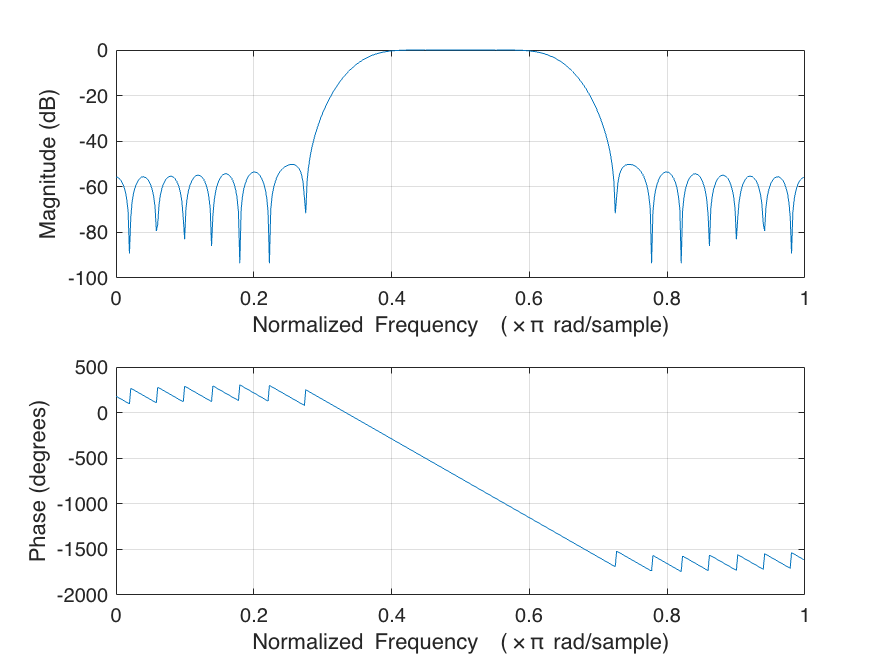

freqz(b,1,512)

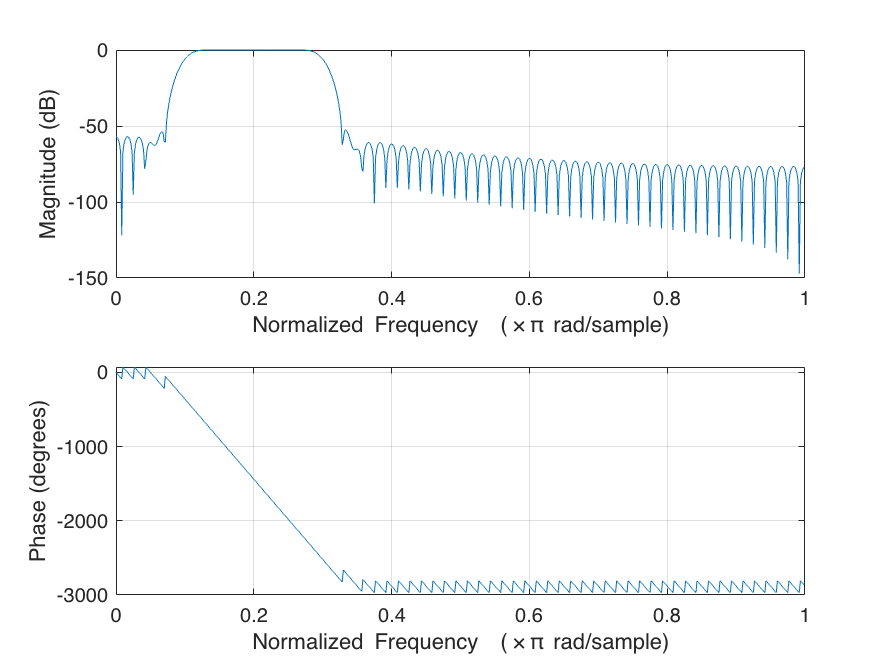


% user created
naples = fir1(120,[.1, .3]);
freqz(naples,1,600)

Load `chirp.mat`. The file contains a signal, `y`, that has most of its power above `Fs/4`, or half the Nyquist frequency. The sample rate is 8192 Hz.

Design a 34th-order FIR highpass filter to attenuate the components of the signal below `Fs/4`. Use a cutoff frequency of 0.48 and a Chebyshev window with 30 dB of ripple.

FIR highpass filter

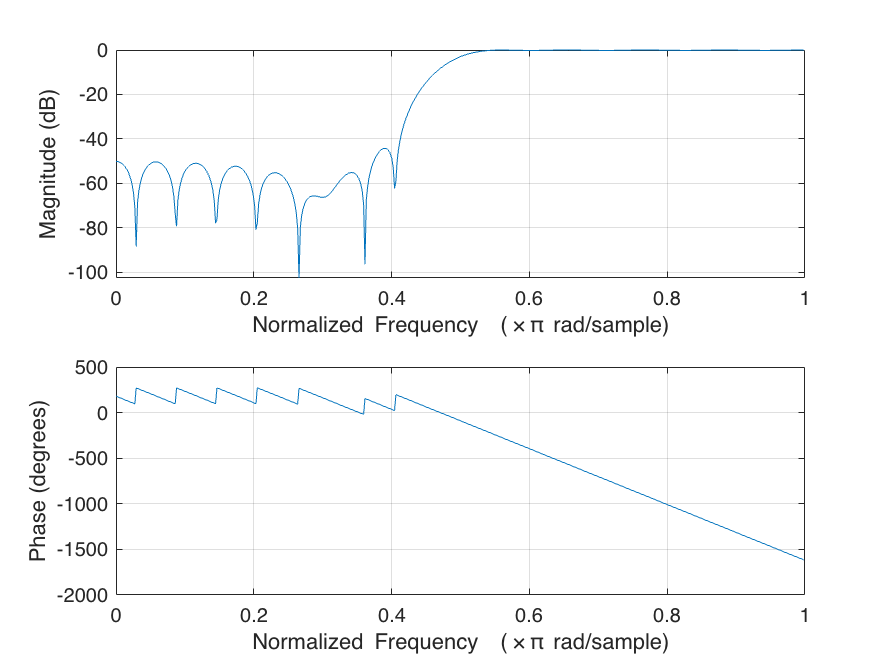


load chirp

t = (0:length(y)-1)/Fs;

bhi = fir1(34,0.48,'high',chebwin(35,30));
freqz(bhi,1)

Filter the signal. Display the original and highpass-filtered signals. Use the same *y*-axis scale for both plots.


outhi = filter(bhi,1,y);

subplot(2,1,1)

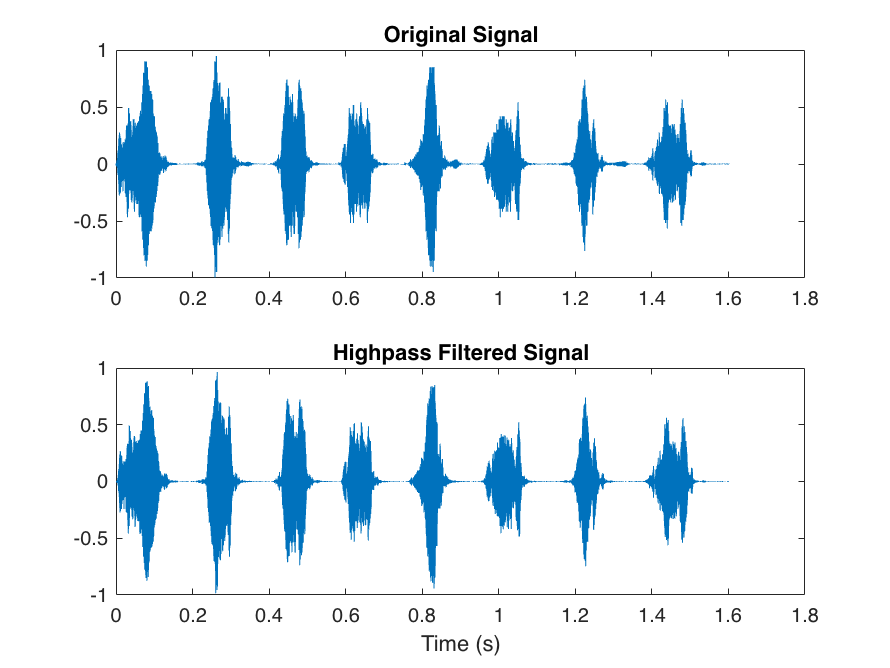

plot(t,y)
title('Original Signal')
ys = ylim;

subplot(2,1,2)
plot(t,outhi)
title('Highpass Filtered Signal')
xlabel('Time (s)')
ylim(ys)

Design a lowpass filter with the same specifications. Filter the signal and compare the result to the original. Use the same *y*-axis scale for both plots.


blo = fir1(34,0.48,chebwin(35,30));

outlo = filter(blo,1,y);

subplot(2,1,1)

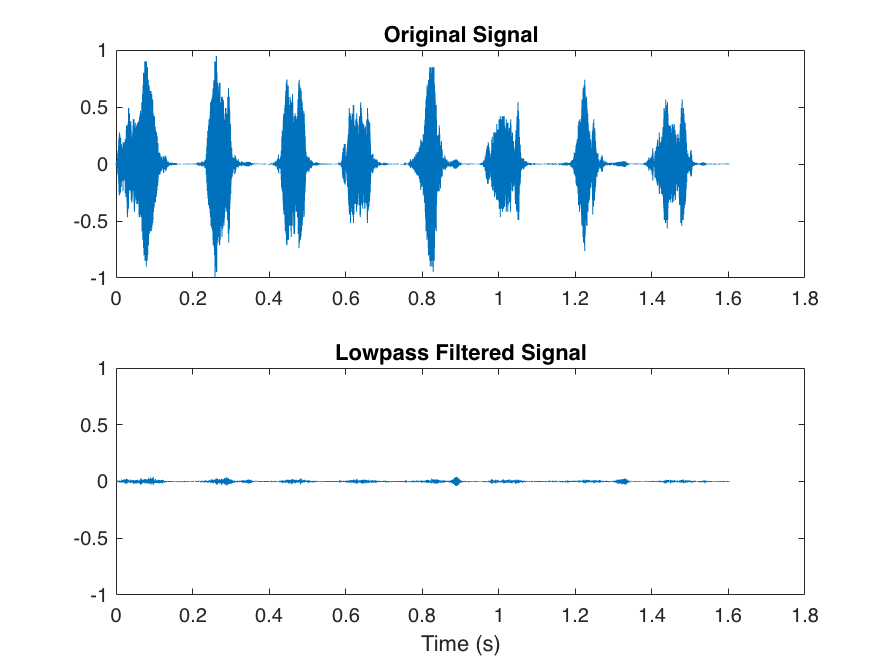

plot(t,y)
title('Original Signal')
ys = ylim;

subplot(2,1,2)
plot(t,outlo)
title('Lowpass Filtered Signal')
xlabel('Time (s)')
ylim(ys)